clear; clc;
cd ~/git/hardDiskControl/discreteTimeControl/
load ../data/sysDT.mat
load ../data/Gz.mat
load ../data/plantTF.mat
load ../data/sysCT.mat

riseTime = 0.052333; %seconds
Ts = riseTime/10;

maxDamp = -log(0.05)/sqrt(pi^2+log(0.05)^2);
degMaxDamp = rad2deg(acos(maxDamp));

mag1 = 100;
phase1 = degMaxDamp;
pole1 = -mag1*cosd(phase1)+mag1*sind(phase1)*1i;
pole1c = -mag1*cosd(phase1)-mag1*sind(phase1)*1i;

mag2 = 1000;
phase2 =degMaxDamp/5;
pole2 = -mag2*cosd(phase2)+mag2*sind(phase2)*1i;
pole2c = -mag2*cosd(phase2)-mag2*sind(phase2)*1i;

poles = [pole1; pole1c; pole2; pole2c];

zPoles = exp(poles.*Ts);
[F, prec] = place(sysDT.A,sysDT.B,zPoles);
Aplaced = sysDT.A-sysDT.B*F;
sysDT = ss(Aplaced,sysDT.B,sysDT.C,sysDT.D,Ts);
sysDT.B = sysDT.B/dcgain(sysDT);

now we will create the delayed system

Ad = [sysDT.A sysDT.B;
      zeros(1,4) 0];
Bd = [zeros(4,1); 1];
Cd = [sysDT.C 0];
Dd = sysDT.D;
sysDTd = ss(Ad,Bd,Cd,Dd,Ts);

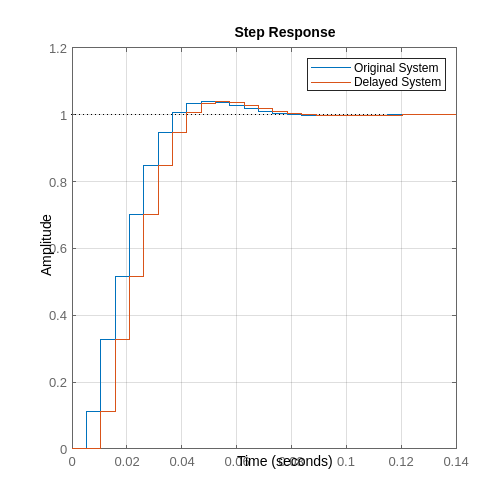

figure('Position', [0 0 1000 1000]);clf;hold on;
step(sysDT)
step(sysDTd); grid on;
legend("Original System", "Delayed System")